# USV Proportional Control Design

## USV Surge Proportional Control

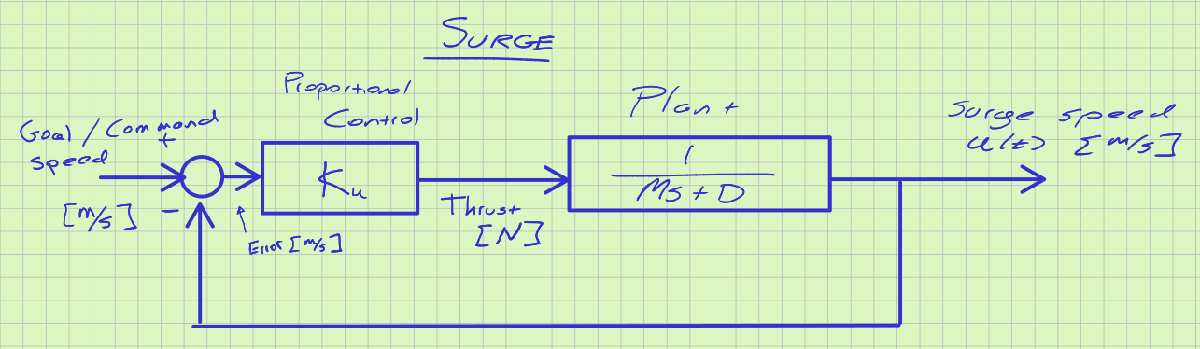

For surge, the close-loop transfer function is


$$T_u = \frac{K_u}{Ms + (D+K_u)} = K_u/(D+K_u) \frac{ 1 } { (M/(D+K_u)) s + 1}.
$$


We can identify that the close-loop system is first-order, the time constant is


$$\tau = M/(D+K_u)$$


and the DC gain of the system is


$$K_{dc} =  K_u/(D+K_u)
$$


which tells us that the overshoot will always be zero and that as we increase $K_u$, the time constant will increase and the gain will approach 1.0. 

Generate the Plant transfer function

% Parameters
M = 36;
D = 18.75;
% Plant
Gu = tf(1,[M D])


Gu =
 
       1
  ------------
  36 s + 18.75
 
Continuous-time transfer function.



For the assignment, you only needed to find a single value of the proportional control gain that satisfied the design constraints.  Here we loop through a number of valuest to see how "turning the know" changes the step response.

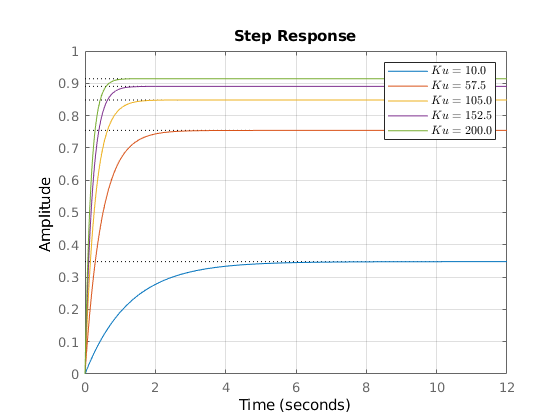

figure(1);
clf()
% Vector of proportional gain values and to hold metrics
KU = linspace(10,200,5);
tr = zeros(size(KU));
sse = zeros(size(KU));
lstr = {};
for ii = 1:length(KU)
    Ku = KU(ii); 
    Tu = feedback(Ku*Gu,1);
    lstr{ii} = sprintf('$Ku=%.1f$',Ku);
    step(Tu);
    st = step(Tu);
    s = stepinfo(Tu);
    tr(ii) = s.RiseTime;
    sse(ii) = abs(1-st(end));
    hold on
end
legend(lstr,'Interpreter','latex')
grid('on')
ylim([0 1])

In Figure we see the same thing we inferred with the equations above, that the speed of the response increases with gain (the time constant is reduced with increasing $K_u$) as well as the steady-state error, but we can never drive the steady-state error to zero.  This is because the system is "Type 0" which we'll learn about in the next section.

And also plot the Rise Time and Steady State Error as a function of the Proportional Gain.

figure(2);
clf()
yyaxis left;
plot(KU,tr);
ylabel('Rise Time [s]')
xlabel('Proportional Gain, $K_u$, [N/(m/s)]','Interpreter','latex')
yyaxis right;
plot(KU,sse);
ylabel('Steady State Error [m/s]')
grid on

Add lines to illustrate the performance constraints.  Rise time less that 2.0 s.

yyaxis left;
yline(2.0,'b--','linewidth',2);

Steady-state error less thatn 0.2 m/s.

yyaxis right;
yline(0.2,'r--','linewidth',2);

Which shows that...

- As long as $K_u > 80$, both design requirements are satisfied

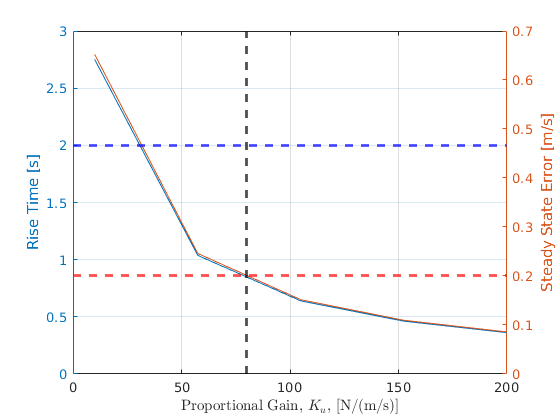

xline(80,'k--','linewidth',2);

- We can infinitely increase $K_u$ without causing instabiliy!

- The overshoot constraint never comes into play.  The closed-loop response is first-order, so overshoot is always zero.

## Yaw Proportional Control

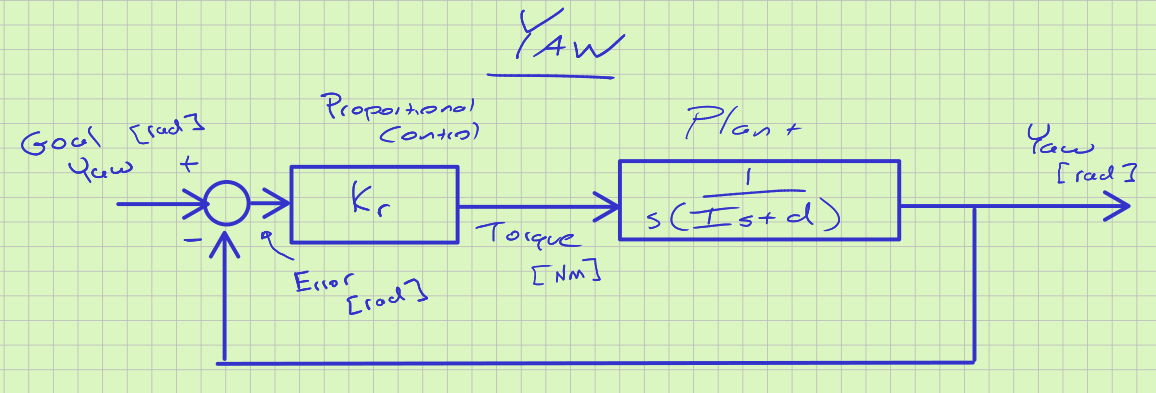

For yaw control, the plant transfer function is different and the resulting closed-loop equivalent transfer function is

$T_r = \frac{K_r}{Is^s + Ds +K_r} = \frac{K_r/I}{s^s + (D/I) s + (Kr/I)}
$.

Comparing this to our canonical second-order transfer funtion, we note the following:

- The DC gain is always 1.0, independent of the proportioanl control gain - so at steady-state the input and output will be the same, so zero steady state error.  

- The natural frequency, $\omega_n = \sqrt{K_r/I$will increase with increasing $K_r$ and 

- The damping ratio $\zeta = (D/I) / (2 \omega_n)$ will decrease with increasing $K_r$  - which means turning up the control gain will generate increasing overshoot  

Again we look at a series of values for the proportional control gain 

(**For the assignment you needed to find any of an infinite number of possible solutions to the design problem. Here we are exploring the entire design space to describe all the possible solutions.**)

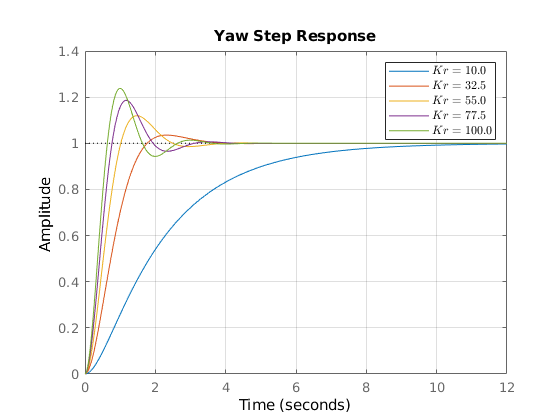

I = 8.35;
d = 24;
KR = linspace(10,100,5);
rt=[];
os=[];
figure(3);
clf()
lstr = {};
for ii = 1:length(KR)
    Kr = KR(ii);
    T = tf(Kr,[I,d,Kr]);
    step(T)
    hold on
    lstr{ii} = sprintf('$Kr=%.1f$',Kr);
    si = stepinfo(T);
    rt(ii)=si.RiseTime;
    os(ii)=si.Overshoot;
end
legend(lstr,'Interpreter','latex')
grid('on')
title('Yaw Step Response')

As we expected, increasing the gain makes the system respond more quickly, but with increasing overshoot.

In this case we cannot increase the gain without bound, we must find values that satisfy the design constraints.  Let's look at rise time and %OS as a function of the control gain.

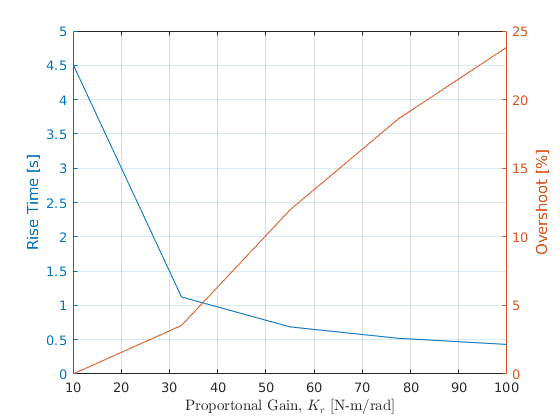

figure(4)
clf()
yyaxis left;
plot(KR,rt)
grid on
xlabel('Proportonal Gain, $K_r$ [N-m/rad]','Interpreter','latex')
ylabel('Rise Time [s]')
yyaxis right;
plot(KR,os)
ylabel('Overshoot [%]')

And then find the threshold values using interpolation.


rt_goal = 0.75;
kr1 = interp1(rt,KR,rt_goal)

kr1 = 51.7333

yyaxis left;
xline(kr1,'b--','linewidth',2);

os_goal = 15.0;
kr2 = interp1(os,KR,os_goal)

kr2 = 65.2915

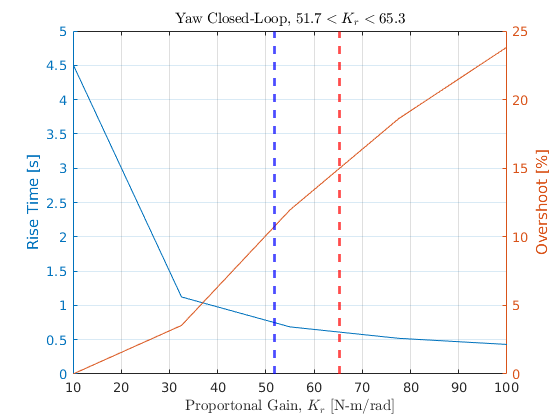

yyaxis right;
xline(kr2,'r--','linewidth',2);

tstr = sprintf('Yaw Closed-Loop, $ %.1f <  K_r  < %.1f$',kr1,kr2);
title(tstr,'Interpreter','latex')

#### Yaw design example

Choose one value for $K_r$ in the solutio range to verify that it meets the requirements.

Kr = 60;

Set the input step size to 1.57

opt = stepDataOptions('StepAmplitude',pi/2);

Plot closed-loop step response.

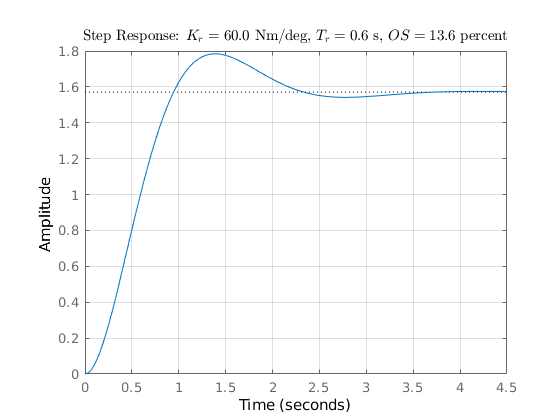

T = tf(Kr,[I,d,Kr]);
figure(5)
clf()
step(T,opt);
grid('on')
s = stepinfo(T);
title(sprintf('Step Response: $K_r=%0.1f$ Nm/deg, $T_r=%0.1f$ s, $OS=%.1f$ percent',Kr,s.RiseTime,s.Overshoot),'Interpreter','latex')